%Goes through text file and converts numbers into an array of strings

data = readlines("\\Client\C$\MATLAB\UnclassifiedPatientData.txt");

%Calculates the length of the data file
x = length(data);

%Neural network is very specific about how many inputs it takes. This loop
%reduces the size of the text file for the network to work

i = 1;
while x > 4096
    data(i) = [];
    i = i+1;
    x = length(data);
end

%Creates a blank 1x1 cell
c = cell(1, 1);

%Populates the 1x1 cell with the data from before and converts it into a
%double
c{1} = str2double(data);

%Changes the configuration of data to 1x4096
reData = reshape(str2double(data), 1, 4096);

%These 2 lines load and open the trained neural network to be used later
s1 = load("M:\trainNet.mat");
trainNet = s1.trainNet;

%Uses the neural network to classify what the data sample was based on the
%trained labels
t = trainNet.classify(reData);

%Displays what the label that was calssified is for testing purposes
disp(t);

     Pre-seizure 



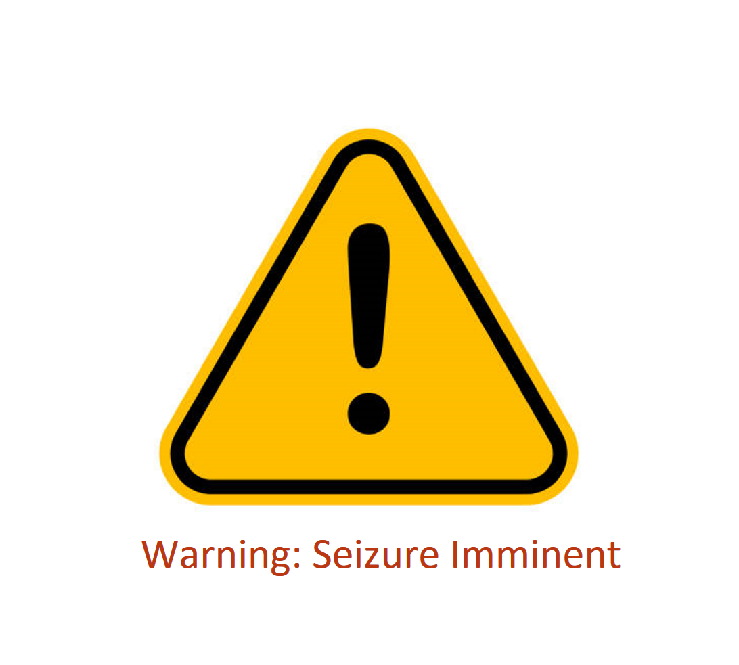


%Cmopares to classification to the below conditions to warn user that a
%seizure event is about to happen
if t == 'Pre-seizure' | t == 'Seizure'
    imshow("\\Client\C$\MATLAB\Warning_ Seizure Imminent.png")
    
else 
end 